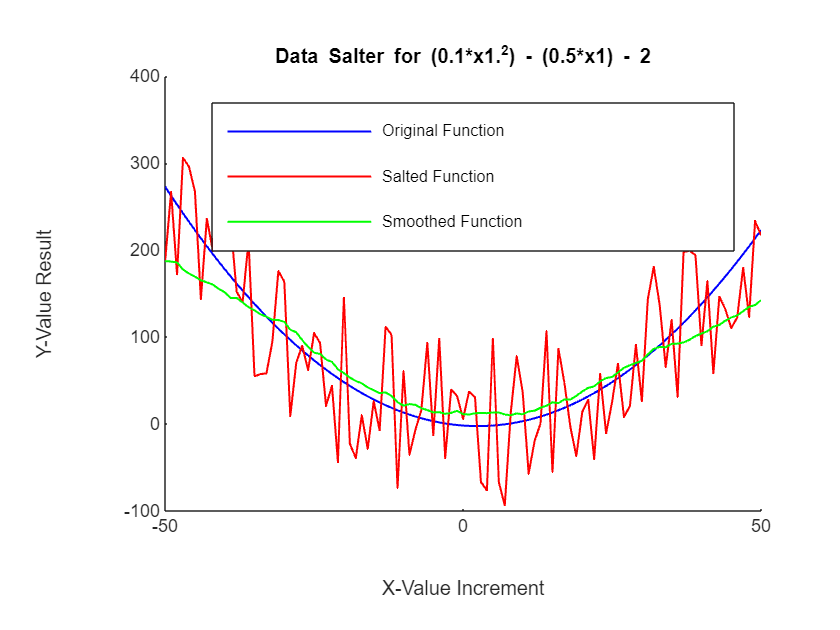

% Written by Mia Watts

%{
This is a MATLAB plotter, salter, and smoother to go along
with the second project in Probability and Applied Statistics.
PART 1 -------------------------------------------------------------
The first block of code plots, salts, and smooths
(0.1*x.^2) - (0.5*x) - 2.
%}

% Ensures that the plotted lines are all on the same graph.
hold on
figure(1)
% Assigns x to a range of values from -50 to 50, incrementing by 1.
x1 = -50:1:50;
% Assigns y to the first formula.
y1 = (0.1*x1.^2) - (0.5*x1) - 2;

% Salts the values using a random value.
saltedValues1 = y1 + ((rand(size(y1)) * 200) - 100);
% Smooths the values using MATLAB's movmean function and a
% second parameter of 38 to get the graph as close to the original
% as possible given the averages.
smoothedValues1 = movmean(saltedValues1, 38);

% Plots the original, salted, and smoothed values and adds a legend.
plot(x1, y1, "b", x1, saltedValues1, "r", x1, smoothedValues1, "g", LineWidth=1)
legend("Original Function", "Salted Function", "Smoothed Function")
% Labels the graph.
title("Data Salter for (0.1*x1.^2) - (0.5*x1) - 2")
xlabel("X-Value Increment")
ylabel("Y-Value Result")

% Prevents the next graph from plotting on this one.
hold off


% PART 2 -------------------------------------------------------------
% This block of code plots, salts, and smooths sin(2x).
% Ensures that the plotted lines are all on the same graph.
hold on

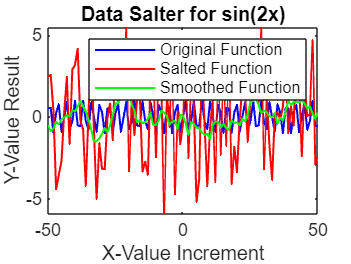

figure(2)
% Assigns x to a range of values from -50 to 50, incrementing by 1.
x2 = -50:1:50;
% Assigns y to the second formula.
y2 = sin(2*x2);

% Salts the values using a random value.
saltedValues2 = y2 + ((rand(size(y2)) * 10) - 5);
% Smooths the values using MATLAB's movmean function and a
% second parameter of 10 to get the graph as close to the original
% as possible given the averages.
smoothedValues2 = movmean(saltedValues2, 10);

figure(2)
% Plots the original, salted, and smoothed values and adds a legend.
plot(x2, y2, "b", x2, saltedValues2, "r", x2, smoothedValues2, "g", LineWidth=1)
legend("Original Function", "Salted Function", "Smoothed Function")
% Labels the graph.
title("Data Salter for sin(2x)")
xlabel("X-Value Increment")
ylabel("Y-Value Result")

% Prevents the next graph from plotting on this one.
hold off


% PART 3 -------------------------------------------------------------
%{
This block of code plots, salts, and smooths 
3cos(x) – 5cos(2x) – 2cos(3x) – cos(4x).
%}
% Ensures that the plotted lines are all on the same graph.
hold on

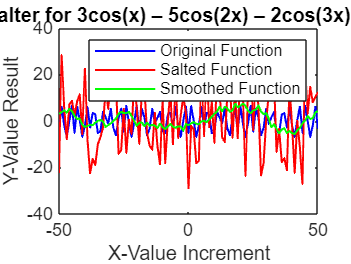

figure(3)
% Assigns x to a range of values from -50 to 50, incrementing by 1.
x3 = -50:1:50;
% Assigns y to the third formula.
y3 = (3*cos(x3)) - (5*cos(2*x3)) - (2*cos(3*x3)) - cos(4*x3);

% Salts the values using a random value.
saltedValues3 = y3 + ((rand(size(y3)) * 50) - 25);
% Smooths the values using MATLAB's movmean function and a
% second parameter of 14 to get the graph as close to the original
% as possible given the averages.
smoothedValues3 = movmean(saltedValues3, 14);

% Plots the original, salted, and smoothed values and adds a legend.
plot(x3, y3, "b", x3, saltedValues3, "r", x3, smoothedValues3, "g", LineWidth=1)
legend("Original Function", "Salted Function", "Smoothed Function")
% Labels the graph.
title("Data Salter for 3cos(x) – 5cos(2x) – 2cos(3x) – cos(4x)")
xlabel("X-Value Increment")
ylabel("Y-Value Result")

% Prevents the next graph from plotting on this one.
hold off